# Microgrid EMS Demonstration Code 

# (Using Day-Ahead Linear Program Case as an Example)

This repository provides a complete framework for implementing a basic day-ahead linear-program-based EMS for a grid-connected microgrid. It serves as a foundation for users to develop more advanced EMS methods. The code is well organized, and users can easily define the input information or modify the grid topology as needed. For demonstration purposes, two ten-bus test cases are included.

Our work

#### "Efficient MPC-Based Energy Management System for Secure and Cost-Effective Microgrid Operations", by [Hanyang He](https://arxiv.org/search/eess?searchtype=author&query=He,+H), [John Harlim](https://arxiv.org/search/eess?searchtype=author&query=Harlim,+J), [Daning Huang](https://arxiv.org/search/eess?searchtype=author&query=Huang,+D), [Yan Li](https://arxiv.org/search/eess?searchtype=author&query=Li,+Y)

was developed based on this framework. If this EMS framework is helpful for your research, please consider citing our paper.

**The code includes:**

1. Microgrid setup;

2. Inverter parameter initialization;

3. Electricity price initialization;

4. Battery-energy storage system initialization;

5. Load and solar power profile preparation (forecasting);

7. Day-ahead EMS scheduling using linear programming (LP);

8. Simulation of EMS scheduling results.

clear
clc

rng(0)

frontsize=14;
ExportFigForPaper=0;

dt=1/900;

dt_pre=900*dt;% Then 900dt=1h
DecisionLevelSteps=24;%  24 steps a day for 1h
t_deci = 0:1:23;


t = 0:dt:dt_pre-dt;
t_sim=0:dt:dt_pre*DecisionLevelSteps-dt;

dt_deci=900*dt;
deciFreqTime=dt_pre/dt_deci;%decision frequency time 

### Microgrid setup

10bus-case1 and case2      

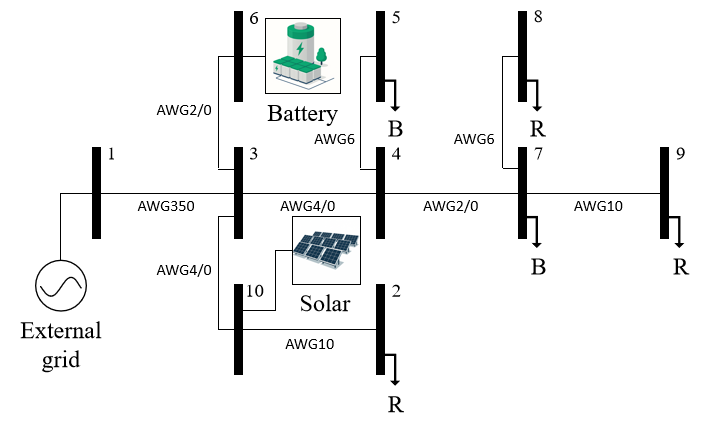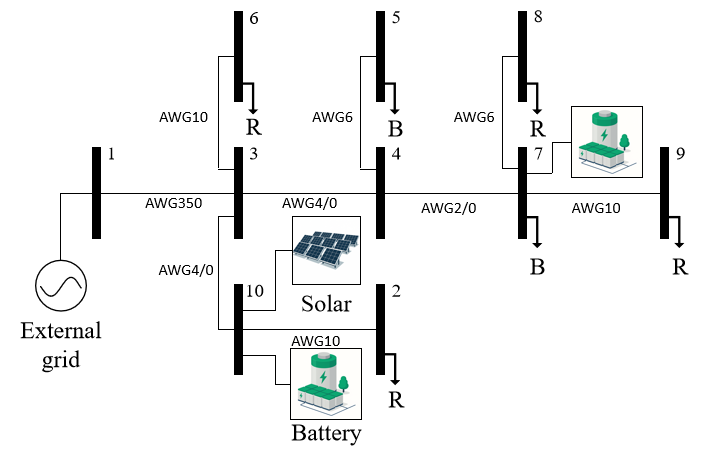  

PF=0.9;
PF_DieselG=0.85;

BusOfSlack=1;

S_base=1e6;%VA (1MVA)
V_base=480;%V
I_base=S_base/(V_base*sqrt(3));%A
Z_base=V_base^2/S_base;%ohm

Vmin=0.90;
Vmax=1.10;

% plan1================
% Topology='10bus-case1';
% BusNum=10;
% residential_node=[2 8 9];
% business_node=[5 7];
% BusOfBattery=[6];
% BusOfPV=[10];

% residentialPower=[0.0127;0.04;0.0128];%MW
% businessPower=[0.0425;0.0612;];%MW
% PVInv_P_rateIn=0.2;%MW
% BatteryInv_P_rateIn=0.15;%MW
% DieselG_P_rate=0;%MW

% Xm_g_batt1 = 0.15;
% Xm_g_batt2 = 0.15;
% Xm_g_solar1 = 0.15;
% Xm_g=[Xm_g_batt1;Xm_g_batt2;Xm_g_solar1];

% brhID=1;% Current profile of the most overloaded branch for plot

% plan2==============
Topology='10bus-case2';
BusNum=10;
residential_node=[2 6 8 9];
business_node=[5 7];
BusOfBattery=[7 10];
BusOfPV=[10];
BusOfDieselG=[ ];

residentialPower=[0.01275;0.03;0.04;0.01275;];%MW
businessPower=[0.0425;0.0612;];%MW
PVInv_P_rateIn=0.25;%MW
BatteryInv_P_rateIn=0.15;%MW
DieselG_P_rate=0;%MW

Xm_g_batt1 = 0.15;
Xm_g_batt2 = 0.15;
Xm_g_solar1 = 0.15;
Xm_g=[Xm_g_batt1;Xm_g_batt2;Xm_g_solar1];

brhID=7;% Current profile of the most overloaded branch for plot

%=====================


ResiUserNum=length(residential_node);
BusiUserNum=length(business_node);
BatteryNum=length(BusOfBattery);
SolarNum=length(BusOfPV);

[Bus_Prate,idx_P_PV,idx_Pbatt,idx_Pbusi,idx_Presi] = busdata(residential_node,business_node,BusOfPV,BusOfBattery,BusNum,PF,residentialPower,businessPower,PVInv_P_rateIn,BatteryInv_P_rateIn);

Load_P_rate=Bus_Prate(:,idx_Pbusi)+Bus_Prate(:,idx_Presi);%MW; note: if one node contains different loads, we cannot combine them together.
Load_Q_rate=Bus_Prate(:,idx_Pbusi+1)+Bus_Prate(:,idx_Presi+1);%MW;
PVInv_P_rate(BusOfPV,1)=Bus_Prate(BusOfPV,idx_P_PV);%MW; rated power of PV inverter
BatteryInv_P_rate(BusOfBattery,1)=Bus_Prate(BusOfBattery,idx_Pbatt);%MW; rated power of Battery inverter
S_DieselG_vec=zeros(BusNum,1);
S_DieselG_vec(BusOfDieselG,1)=DieselG_P_rate.*(1+1j*tan(acos(PF_DieselG)));

[Line, LineLimits]= linedata(Topology,Z_base,I_base);
Impedance = Line(:,3) + 1j.*Line(:,4);
Admittance = 1./Impedance;

% Admittance Matrix
Y_Bus = admittance_matrix(BusNum,length(Line(:,1)),Admittance,Line);
G = real(Y_Bus);
B = imag(Y_Bus);

### Inverter parameter initialization

Zmv_g=ones(length(Xm_g),1)*(0+1j*0.0);%pu virtual impedance of inverter controller

V_DC=2;

f_rate=60;
w_rate=2*pi*f_rate;

dw_set=0;
dw0=0;

Vset=1;

% inverter for battery storage
K_Vdp=0;% GFL mode
K_fdp=0;% GFL mode

KP_PLL_vf=10;KI_PLL_vf=0.1;
% ----f (P) branch-----
KP_outer_f = 0.2;KI_outer_f = 10;
KP_inner_f = 0.1;KI_inner_f = 40;
% ----v (Q) branch----
KP_outer_v = 0.2;KI_outer_v = 10;
KP_inner_v = 0.1;KI_inner_v = 40;

% inverter for PV 
KP_PLL_pq=KP_PLL_vf;KI_PLL_pq=KI_PLL_vf;
% ----f (P) branch-----
KP_outer_p = KP_outer_f;KI_outer_p = KI_outer_f;
KP_inner_p = KP_inner_f;KI_inner_p = KI_inner_f;
% ----v (Q) branch----
KP_outer_q = KP_outer_v;KI_outer_q = KI_outer_v;
KP_inner_q = KP_inner_v;KI_inner_q = KI_inner_v;


idx=1;
for ii=1:BatteryNum
    controlParams(idx,1)=KP_PLL_vf;idx=idx+1;
    controlParams(idx,1)=KI_PLL_vf;idx=idx+1;
    controlParams(idx,1)=KI_outer_v;idx=idx+1;
    controlParams(idx,1)=KI_outer_f;idx=idx+1;
    controlParams(idx,1)=KI_inner_v;idx=idx+1;
    controlParams(idx,1)=KI_inner_f;idx=idx+1;
    controlParams(idx,1)=KP_outer_v;idx=idx+1;
    controlParams(idx,1)=KP_outer_f;idx=idx+1;
    controlParams(idx,1)=KP_inner_v;idx=idx+1;
    controlParams(idx,1)=KP_inner_f;idx=idx+1;
end

for ii=1:SolarNum
    controlParams(idx,1)=KP_PLL_pq;idx=idx+1;
    controlParams(idx,1)=KI_PLL_pq;idx=idx+1;
    controlParams(idx,1)=KI_outer_p;idx=idx+1;
    controlParams(idx,1)=KI_outer_q;idx=idx+1;
    controlParams(idx,1)=KI_inner_p;idx=idx+1;
    controlParams(idx,1)=KI_inner_q;idx=idx+1;
    controlParams(idx,1)=KP_outer_p;idx=idx+1;
    controlParams(idx,1)=KP_outer_q;idx=idx+1;
    controlParams(idx,1)=KP_inner_p;idx=idx+1;
    controlParams(idx,1)=KP_inner_q;idx=idx+1;
end

### Electricity price initialization

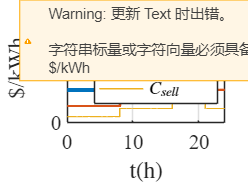

% grid electricity price
c_buy_valley_residential  = 0.12;% dollar/kWh
c_buy_offpeak_residential=0.2;% dollar/kWh
c_buy_onpeak_residential=0.35;% dollar/kWh

c_buy_valley_business     = 0.06;% dollar/kWh
c_buy_offpeak_business=0.12;% dollar/kWh
c_buy_onpeak_business=0.25;% dollar/kWh

c_sell_valley = 0.02;% dollar/kWh
c_sell_offpeak=0.05;% dollar/kWh
c_sell_onpeak=0.10;% dollar/kWh

idx_valley = (t_sim >= 0)   & (t_sim < 8);
idx_flat1  = (t_sim >= 8)   & (t_sim < 16);
idx_peak   = (t_sim >= 16)  & (t_sim < 21);
idx_flat2  = (t_sim >= 21)  & (t_sim < 24);

C_buy_residential=ones(size(t_sim));
C_buy_residential(idx_valley) = c_buy_valley_residential;
C_buy_residential(idx_flat1)  = c_buy_offpeak_residential;
C_buy_residential(idx_peak)   = c_buy_onpeak_residential;
C_buy_residential(idx_flat2)  = c_buy_offpeak_residential;

C_buy_business=ones(size(t_sim));
C_buy_business(idx_valley) = c_buy_valley_business;
C_buy_business(idx_flat1)  = c_buy_offpeak_business;
C_buy_business(idx_peak)   = c_buy_onpeak_business;
C_buy_business(idx_flat2)  = c_buy_offpeak_business;

C_sell=ones(size(t_sim));
C_sell(idx_valley) = c_sell_valley;
C_sell(idx_flat1)  = c_sell_offpeak;
C_sell(idx_peak)   = c_sell_onpeak;
C_sell(idx_flat2)  = c_sell_offpeak;

% system level price vector for decision
C_buy_residential_declevel=C_buy_residential(1:dt_pre/dt:end);
C_buy_residential_declevel0=C_buy_residential_declevel(1,1:24);
C_buy_residential_declevel=[C_buy_residential_declevel0 C_buy_residential_declevel0];
C_buy_business_declevel=C_buy_business(1:dt_pre/dt:end);
C_buy_business_declevel0=C_buy_business_declevel(1,1:24);
C_buy_business_declevel=[C_buy_business_declevel0 C_buy_business_declevel0];
C_sell_declevel=C_sell(1:dt_pre/dt:end);
C_sell_declevel0=C_sell_declevel(1,1:24);
C_sell_declevel=[C_sell_declevel0 C_sell_declevel];

figure
hold on
plot(t_sim,C_buy_residential,'LineWidth',3)
plot(t_sim,C_buy_business,'LineWidth',2)
plot(t_sim,C_sell,'LineWidth',1)

hold off
xlabel('t(h)', 'Interpreter', 'latex');ylabel('$/kWh', 'Interpreter', 'latex')
legend({'$C_{buy.resid}$','$C_{buy.busi}$','$C_{sell}$'}, 'Interpreter', 'latex')
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
xlim([0,24]);ylim([0,0.4])
grid on
box on

diesel generator price

C_dieselG=0.3;%$/kWh

### Battery-energy storage system information

SOCmax=0.9;
SOCmin=0.2;
SOC(1:BatteryNum,1)=0.30;% initial charging state of energy storage, for SOC, each row is a battery

% battery cost
Batt_Duration=5;% h
Ncyc=5000;% battery life cycle
if BatteryNum>0
    EbattMax=BatteryInv_P_rate(BusOfBattery(1),1)*Batt_Duration;% Battery capacity MWh
else
    EbattMax=0;
end
C_battUnitPrice=300;%dollar/kWh
C_batt_total=EbattMax*1000*C_battUnitPrice;%dollar
inta_batt_ch=0.95;% charging efficiency
inta_batt_dis=0.95;% discharging efficiency

if BatteryNum>0
C_deg=C_batt_total/(EbattMax*1000*Ncyc*2);% degradation cost
else
C_deg=0;
end

### Load curve preparation

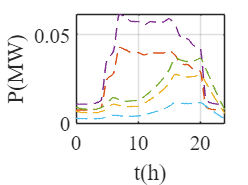

% Treat the provided load power as the rated power, whose per unit value is 1.
PF_box=abs(Load_P_rate./sqrt(Load_P_rate.^2+Load_Q_rate.^2));% Assume constant PF


lag = 6;  % In the autoregressive model, use the previous 'lag' time points as input
TargetSampleDay=1; % 1: use one local sample day; 0: zero-shot;
SourceSampleDay=1; % 1: use five transfer sample days; 0: not use;
regularPeriod=0; % 1: regular period; 0: irregular period

% load residential load data
Pmat_source0=[];
Pmat_target0=[];
load('USA_PAState_Residential.mat');
    temp=USA_PAState_Residential.ElectricityFacilitykWHourly;
    P_PAresidential_TMY3=temp(2:end);
    PmatYear_PA=reshape(P_PAresidential_TMY3,24,length(P_PAresidential_TMY3)/24);
    if SourceSampleDay==1
        if regularPeriod==1
            Pmat_source0=[PmatYear_PA(:,2:6)];
        else
            Pmat_source0=[PmatYear_PA(:,2:6)]+0.05*randn(size(PmatYear_PA(:,2:6)));
        end
    end
    if TargetSampleDay==1
        if regularPeriod==1
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,5:6) PmatYear_PA(:,7)];
            Ptarget_sp=PmatYear_PA(:,5:6);
        else
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,198:199) PmatYear_PA(:,200)];
            Ptarget_sp=PmatYear_PA(:,198:199);
        end
    else
        if regularPeriod==1
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,7)];
        else
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,7)]+0;
        end
    end
    Pmax=max(max(Pmat_source0));
    Pmat_source=Pmat_source0/Pmax;
    Pmat_target=Pmat_target0/Pmax;

    Pmat_residential=[Pmat_source Pmat_target];


% load large office load data
Pmat_source0=[];
Pmat_target0=[];
load('USA_PAState_RefBldgLargeOfficeNew2004v1.mat');
    temp=USA_PAState_RefBldgLargeOfficeNew2004v1.ElectricityFacilitykWHourly;
    P_PAlargeOffice_TMY3=temp(2:end);
    PmatYear_PA=reshape(P_PAlargeOffice_TMY3,24,length(P_PAlargeOffice_TMY3)/24);
    if SourceSampleDay==1
        if regularPeriod==1
            Pmat_source0=[Pmat_source0 PmatYear_PA(:,2:6)];
        else
            Pmat_source0=[Pmat_source0 PmatYear_PA(:,195+3:199+2)+40*randn(size(PmatYear_PA(:,198:201)))];
        end
    end
    if TargetSampleDay==1
        if regularPeriod==1
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,5:6) PmatYear_PA(:,9)];
            Ptarget_sp=PmatYear_PA(:,5:6);
        else
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,137:138) PmatYear_PA(:,139)];
            Ptarget_sp=PmatYear_PA(:,137:138);
        end
    else
        if regularPeriod==1
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,9)];
            Ptarget_sp=PmatYear_PA(:,5:6);
        else
            Pmat_target0=[Pmat_target0 PmatYear_PA(:,202)];
        end
    end
    Pmax=max(max(Pmat_source0));
    Pmat_source=Pmat_source0/Pmax;

    Pmat_target=Pmat_target0/Pmax;

    Pmat_largeOffice=[Pmat_source Pmat_target];


[X_train_largeOffice, dy_train_largeOffice] = build_dataset(Pmat_largeOffice, 1:size(Pmat_largeOffice,2)-2, lag, dt_pre,1);
[X_train_residential, dy_train_residential] = build_dataset(Pmat_residential, 1:size(Pmat_residential,2)-2, lag, dt_pre,1);
curve_business=Pmat_largeOffice(:,end)';
curve_residential=Pmat_residential(:,end)';

% forecasting curve for scheduling
PF_box(isnan(PF_box))=0;
PowAngle=acos(PF_box);

P_st=Load_P_rate;
% Pload_box_1day1h=[zeros(1,length(t_deci)); curve_residential; zeros(1,length(t_deci)); zeros(1,length(t_deci)); curve_business; zeros(1,length(t_deci)); curve_business; curve_residential; curve_residential; zeros(1,length(t_deci))].*repmat(P_st,1,length(t_deci));
Pload_box_1day1h=zeros(BusNum,length(t_deci));
for ii=1:BusNum
    if ismember(ii,business_node)
        Pload_box_1day1h(ii,:)=curve_business*P_st(ii);
    elseif ismember(ii,residential_node)
        Pload_box_1day1h(ii,:)=curve_residential*P_st(ii);
    end
end
Qload_box_1day1h=Pload_box_1day1h.*tan(PowAngle);%Qload_box_syslevel(isnan(Qload_box_syslevel))=0;

Pload_box_syslevel_true2day_idealPredfordebug=[Pload_box_1day1h Pload_box_1day1h];

if lag>1
    Pload_box_lag1day1h=[Pload_box_1day1h(:,end-lag+2:end) Pload_box_1day1h];
    Qload_box_lag1day1h=[Qload_box_1day1h(:,end-lag+2:end) Qload_box_1day1h];
end

% numerically rebuild the true load curve at real time step size for simulation
Nvari=length(t_sim);

curve_business_true = (UniversalCurve(t_deci, curve_business,t_sim, 'pchip'));
curve_residential_true = (UniversalCurve(t_deci, curve_residential,t_sim, 'pchip'));


% Pload_true_box=-[zeros(1,Nvari); curve_residential_true; zeros(1,Nvari); zeros(1,Nvari); curve_business_true; zeros(1,Nvari); curve_business_true; curve_residential_true; curve_residential_true; zeros(1,Nvari)].*repmat(P_st,1,Nvari);
Pload_true_box=zeros(BusNum,length(t_sim));
for ii=1:BusNum
    if ismember(ii,business_node)
        Pload_true_box(ii,:)=curve_business_true*P_st(ii);
    elseif ismember(ii,residential_node)
        Pload_true_box(ii,:)=curve_residential_true*P_st(ii);
    end
end
Qload_true_box=Pload_true_box.*tan(PowAngle);%Qload_box(isnan(Qload_box))=0;

Pload_true_box_1daySimstep=Pload_true_box(:,1:dt_deci/dt:end);
if lag>1
    Pload_true_box_lag1daySimstep=[Pload_true_box_1daySimstep(:,end-(lag-1)*dt_pre/dt_deci+1:end) Pload_true_box_1daySimstep];
end
Qload_true_box_lag1daySimstep=Pload_true_box_lag1daySimstep.*tan(PowAngle);

figure
hold on
for ii=1:BusNum
    if ismember(ii,business_node) || ismember(ii,residential_node)
        plot(t_sim,-Pload_true_box(ii,:),'--','LineWidth',1)
    end
end
hold off
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
% legend('Bus2','Bus5','Bus7','Bus8','Bus9')
xlabel('t(h)');ylabel('P(MW)')
xlim([0,24])
grid on
box on

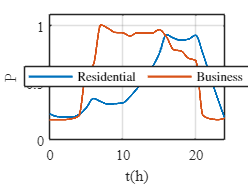


figure
hold on
plot(t_sim,Pload_true_box(residential_node(1),:)/Load_P_rate(residential_node(1)),'-','LineWidth',1.5)
plot(t_sim,Pload_true_box(business_node(1),:)/Load_P_rate(business_node(1)),'-','LineWidth',1.5)
hold off
xlabel('t(h)');ylabel('P')
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
legend({'Residential','Business'},'Interpreter','latex','Location','best','NumColumns',2)
xlim([0,24])
ylim([0,1.1])
grid on
box on

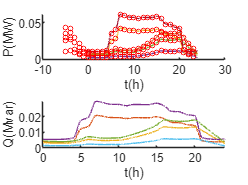


if ExportFigForPaper==1
    w=7.8;%cm
    h=7;%cm
    filename='loadPowerCurve';
    format='pdf';
    figProcess(w, h, filename, format);
end

figure
sz=10;
subplot(2,1,1)
hold on
for ii=1:BusNum
    if ismember(ii,business_node) || ismember(ii,residential_node)
        plot(t_sim,-Pload_true_box(ii,:))
        scatter([t_deci(1,end-lag+2:end)-24 t_deci],-Pload_box_lag1day1h(ii,:),sz,'r')
    end
end

hold off
xlabel('t(h)');ylabel('P(MW)')

subplot(2,1,2)
hold on
for ii=1:BusNum
    if ismember(ii,business_node) || ismember(ii,residential_node)
        plot(t_sim,-Qload_true_box(ii,:))
    end
end
hold off
xlabel('t(h)');ylabel('Q(Mvar)')


% set up load prediction model
best_sigma_largeOffice = 0.184036;
best_lambda_largeOffice = 0.102651;

N_train=size(X_train_largeOffice,1);
for i = 1:N_train
    for j = 1:N_train
        K_train_business(i,j) =compositeKernel(X_train_largeOffice(i,:),X_train_largeOffice(j,:),best_sigma_largeOffice); 
    end
end
alpha_best_largeOffice = (K_train_business + best_lambda_largeOffice * eye(N_train)) \ dy_train_largeOffice;


best_sigma_residential = 0.237881;
best_lambda_residential = 0.058804;

N_train=size(X_train_residential,1);
for i = 1:N_train
    for j = 1:N_train
        K_train_residential(i,j) =compositeKernel(X_train_residential(i,:),X_train_residential(j,:),best_sigma_residential); 
    end
end
alpha_best_residential = (K_train_residential + best_lambda_residential * eye(N_train)) \ dy_train_residential;

### Solar power profile preparation

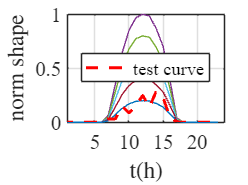

% ------------load PV data---------------------
Pmat_train0=[];
Pmat_test0=[];

data = readtable('2017_pv_raw.csv');
temp=data.Huang_E4102_kW;
P_solarData=temp(1:60:end);
PmatYears=reshape(P_solarData,24,length(P_solarData)/24);

TypicalDay=PmatYears(:,286);
Pmat_train0=[Pmat_train0 TypicalDay TypicalDay TypicalDay TypicalDay 0.8*TypicalDay 0.6*TypicalDay 0.4*TypicalDay 0.2*TypicalDay];
TrueUnusualDay=PmatYears(:,292);
Pmat_test0=[Pmat_test0 0.3*TrueUnusualDay];

Pmat_dictionary0=[TypicalDay 0.9*TypicalDay 0.8*TypicalDay 0.7*TypicalDay 0.6*TypicalDay 0.5*TypicalDay 0.4*TypicalDay 0.3*TypicalDay 0.2*TypicalDay 0.1*TypicalDay];

% ------data preparation------
Pmat0=[Pmat_train0 Pmat_test0];
% normalize
Pmax0=max(TypicalDay);
Pmat=Pmat0/Pmax0;
Pmat(Pmat < 0) = 0;
Pmat_train=Pmat(:,1:end-1);
Pmat_test=Pmat(:,end);

Pmat_dictionary=Pmat_dictionary0/Pmax0;
Pmat_dictionary(Pmat_dictionary < 0) = 0;
Pmat_dictionary_db=[Pmat_dictionary;Pmat_dictionary];

% ------ causal smooth the observed true solar power data (test data)---------
% smWinSize=2;
% Pmat_test = movmean(Pmat_test, [smWinSize-1,0], 1);


figure
hold on
for i=1:size(Pmat,2)-1
    plot(0:1:23,Pmat(:,i)')
end

h3=plot(0:1:23,Pmat(:,end)','Color','r','LineWidth',2,'LineStyle','--');
hold off
xlabel('t(h)','Interpreter','latex');ylabel('norm shape','Interpreter','latex');xlim([1,1*24])
legend([h3], {'test curve'}, 'Location', 'best')
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);grid on;box on;

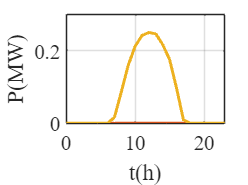



train_idx = 1:size(Pmat_train,2);
test_idx=size(Pmat_test,2);


usedx=1;
[X_train_PV, nextX_train_PV] = build_datasetPV(Pmat_train,train_idx, lag, dt, usedx);
% [X_testPV, nextX_testPV] = build_datasetPV(Pmat_test, test_idx, lag, dt, usedx);

% --------------set up PV prediction model---------------
best_sigma_PV = 0.327047;
best_lambda_PV = 0.348560;

N_train=size(X_train_PV,1);
for i = 1:N_train
    for j = 1:N_train
        K_train_PV(i,j) =compositeKernel(X_train_PV(i,:),X_train_PV(j,:),best_sigma_PV); 
    end
end
alpha_best_PV = (K_train_PV + best_lambda_PV * eye(N_train)) \ nextX_train_PV;

% -------------prepare PV power curve for this application scenario---------------
normdayIndex=2;
curve_solar=Pmat_train(:,normdayIndex)';
P_PV1_curve_1day1h_fore=zeros(BusNum,length(t_deci));
for ii=1:BusNum
    if ismember(ii,BusOfPV)
        P_PV1_curve_1day1h_fore(ii,:)=curve_solar*PVInv_P_rate(ii,1);% The forecasting curve used for making decision has a normal bell shape
    end
end
% P_PV1_curve_1day1h_fore=Pmat_train(:,normdayIndex)'*PVInv_S_rate(BusOfPV(1),1);% The forecasting curve used for making decision has a normal bell shape
P_PV1_curve_lag1day1h_fore=[P_PV1_curve_1day1h_fore(:,end-lag+2:end) P_PV1_curve_1day1h_fore];
% P_PV1_curve_2day1h_idealForefordebug=[P_PV1_curve_1day1h_fore P_PV1_curve_1day1h_fore];

curve_solar_true=Pmat_test(:,end)';
P_PV1_curve_1day1h_true=zeros(BusNum,length(t_deci));
for ii=1:BusNum
    if ismember(ii,BusOfPV)
        P_PV1_curve_1day1h_true(ii,:)=curve_solar_true*PVInv_P_rate(ii,1);% The forecasting curve used for making decision has a normal bell shape
    end
end
% P_PV1_curve_1day1h_true=Pmat_test(:,end)'*PVInv_S_rate(BusOfPV(1),1)*0.5;% The true curve used for plant system has an abnormal shape due to the cloudy day
P_PV1_curve_lag1day1h_true=[P_PV1_curve_1day1h_true(:,end-lag+2:end) P_PV1_curve_1day1h_true];
P_PV1_curve_2day1h_true_idealForefordebug=[P_PV1_curve_1day1h_true P_PV1_curve_1day1h_true];

figure
plot(t_deci,P_PV1_curve_1day1h_fore,'LineWidth',2)
xlabel('t(h)');ylabel('P(MW)')
xlim([0,23])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
grid on 
box on

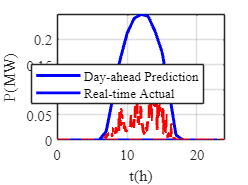


% simulation-time resolution PV curve
load('P_PV_true_dt1min_st.mat')
P_PV_true_dt1min_st(P_PV_true_dt1min_st<0)=0;% here, you can also select a normal day solar curve in '2017_pv_raw.csv' to see the results of a normal day

t_pv=0:1/60:24-1/60;
PV1_curve_st = UniversalCurve(t_pv, P_PV_true_dt1min_st',t_sim, 'pchip');
% PV1_curve = PV1_curve_st*PVInv_S_rate(BusOfPV(1),1);
PV1_curve=zeros(BusNum,length(t_sim));
for ii=1:BusNum
    if ismember(ii,BusOfPV)
        PV1_curve(ii,:)=PV1_curve_st*PVInv_P_rate(ii,1);% The forecasting curve used for making decision has a normal bell shape
    end
end

PV1_curve_1dayDecStep=PV1_curve(:,1:dt_deci/dt:end);
w = 9;                          % window size (odd is better)
PV1_curve_1dayDecStep = movmean(PV1_curve_1dayDecStep, w, 2, 'omitnan');   % row-wise smoothing
if lag>1
    PV1_curve_lag1dayDecStep=[PV1_curve_1dayDecStep(:,end-(lag-1)*dt_pre/dt_deci+1:end) PV1_curve_1dayDecStep];%The measured solar data for MPC at each decision step
end

figure
plot(t_deci, P_PV1_curve_1day1h_fore, 'b-', 'LineWidth', 2); hold on
plot(t_sim, PV1_curve, 'r--', 'LineWidth', 2);
xlabel('t(h)'); ylabel('P(MW)');
xlim([0,24])
legend('Day-ahead Prediction', 'Real-time Actual');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
grid on; box on

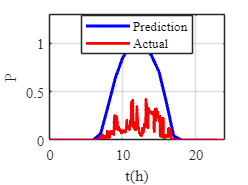


figure
plot(t_deci, P_PV1_curve_1day1h_fore(BusOfPV(1),:)/PVInv_P_rateIn(1), 'b-', 'LineWidth', 2); hold on
plot(t_sim, PV1_curve(BusOfPV(1),:)/PVInv_P_rateIn(1), 'r-', 'LineWidth', 2);
xlabel('t(h)'); ylabel('P');
xlim([0,24])
ylim([0,1.3])
legend('Prediction', 'Actual','Location','best');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
grid on; box on

if ExportFigForPaper==1
    w=7.8;%cm
    h=7;%cm
    filename='solarPowerCurve';
    format='pdf';
    figProcess(w, h, filename, format);
end

## Day-ahead EMS scheduling using linear programming (LP)

% x=[...,Pdis[1->24],Pch[1->24],...,Pbuy[1->24],Psell[1->24]]' decision variable format
Kday=24;

% ==============power forecasting for scheduling===================
% ------day-ahead forcast load and Res information--------
decisionStep=1;
predictionStep=1;
S_PV_busBox(:,1:lag)=PV1_curve_lag1dayDecStep(:,decisionStep:dt_pre/dt_deci:decisionStep+(lag-1)*dt_pre/dt_deci);% active power optimization for economic dispatch
S_PV=zeros(BusNum,1);

Sload_busBox(:,1:lag)=Pload_true_box_lag1daySimstep(:,decisionStep:dt_pre/dt_deci:decisionStep+(lag-1)*dt_pre/dt_deci)+1j*Qload_true_box_lag1daySimstep(:,decisionStep:dt_pre/dt_deci:decisionStep+(lag-1)*dt_pre/dt_deci);% active power optimization for economic dispatch
Sload=zeros(BusNum,1);

predictionHorizon=24;
useUpStream=0;
lookAheadStep=0;
for ii=1:predictionHorizon % forecasting before optimization
    StdTime=mod((ii-1+predictionStep-1)*dt_pre,24)/24;
    % % ========== update the next step load and GFL power==========
    % PV prediction (assume local MPPT control)------------
    P_PV_busBoxST(BusOfPV,ii:ii+lag-1)=real(S_PV_busBox(BusOfPV,ii:ii+lag-1))./PVInv_P_rate(BusOfPV,1);
    P_PV_busBoxST(BusOfPV,ii+lag)=max(SolarPredModel(P_PV_busBoxST(BusOfPV(1),ii:ii+lag-1),X_train_PV,best_sigma_PV,alpha_best_PV,Pmat_dictionary_db(predictionStep-1+ii:predictionStep-1+ii+1,:),P_PV1_curve_2day1h_true_idealForefordebug(BusOfPV(1),predictionStep-1+ii+1),ii,useUpStream,lookAheadStep,StdTime),0);
    S_PV_busBox(BusOfPV,ii+lag)=(P_PV_busBoxST(BusOfPV,ii+lag)+1j*0).*PVInv_P_rate(BusOfPV,1);
    
    S_PV(:,ii)=S_PV_busBox(:,ii+lag-1);
    
    % load prediction----------
    Pload_busBoxST(residential_node,ii:ii+lag-1)=real(Sload_busBox(residential_node,ii:ii+lag-1))./P_st(residential_node,1);
    Pload_busBoxST(residential_node,ii+lag)=LoadPredModel(Pload_busBoxST(residential_node(1),ii:ii+lag-1),X_train_residential,best_sigma_residential,alpha_best_residential,StdTime);
    Sload_busBox(residential_node,ii+lag)=(Pload_busBoxST(residential_node,ii+lag)).*P_st(residential_node,1);
    
    Pload_busBoxST(business_node,ii:ii+lag-1)=real(Sload_busBox(business_node,ii:ii+lag-1))./P_st(business_node,1);
    Pload_busBoxST(business_node,ii+lag)=LoadPredModel(Pload_busBoxST(business_node(1),ii:ii+lag-1),X_train_largeOffice,best_sigma_largeOffice,alpha_best_largeOffice,StdTime);
    Sload_busBox(business_node,ii+lag)=(Pload_busBoxST(business_node,ii+lag)).*P_st(business_node,1);
    
    Sload(:,ii)=Sload_busBox(:,ii+lag-1);
end

% ------ideal perfect prediction case------
% Sload=zeros(BusNum,Kday);
% Sload([residential_node business_node],:)=Pload_box_lag1day1h([residential_node business_node],lag:end)+1j*Qload_box_lag1day1h([residential_node business_node],lag:end);
% 
% S_PV=zeros(BusNum,Kday);
% S_PV(BusOfPV,:)=P_PV1_curve_lag1day1h_fore(BusOfPV,lag:end);
% ====================================

% coefficient vector of objective function
Pload_resid=sum(real(Sload(residential_node,:)));
Pload_busi=sum(real(Sload(business_node,:)));
w_c_resid=Pload_resid./(Pload_resid+Pload_busi);
w_c_busi=Pload_busi./(Pload_resid+Pload_busi);
C_buy=C_buy_residential_declevel0.*w_c_resid+C_buy_business_declevel0.*w_c_busi;

batt_coefBox=[];
for ii=1:BatteryNum
    batt_coefBox=[batt_coefBox (1-inta_batt_dis)*C_buy+C_deg*ones(1,Kday) (1-inta_batt_ch)*C_buy+C_deg*ones(1,Kday)];
end
f_linprog=1000*[batt_coefBox...
    C_buy -C_sell_declevel0]*dt_pre;
f_linprog=f_linprog';

% ==========ineq================
M_grid=1e6;
lb=[zeros(1,length(f_linprog))]';

batt_ubBox=[];
for ii=1:BatteryNum
    batt_ubBox=[batt_ubBox BatteryInv_P_rate(BusOfBattery(ii),1)*ones(1,Kday) BatteryInv_P_rate(BusOfBattery(ii),1)*ones(1,Kday)];
end
ub=[batt_ubBox...
    M_grid*ones(1,Kday) M_grid*ones(1,Kday)...
    ]';

% ---SOC----
b_SOC=zeros(Kday*2*BatteryNum,1);% BatteryNum battery
idx=0;
for ii=1:BatteryNum
    b_SOC(idx+1:idx+Kday,1)=(SOCmax-SOC(ii,1))*ones(Kday,1);idx=idx+Kday;
    b_SOC(idx+1:idx+Kday,1)=(SOC(ii,1)-SOCmin)*ones(Kday,1);idx=idx+Kday;
    b_SOC(idx,1,1)=SOC(ii,1)-SOC(ii,1);%total charge >= total discharge in a day
end

A_SOC=zeros(length(b_SOC),length(f_linprog));
idx=0;
for jj=1:BatteryNum
    for i=1:Kday
        A_SOC(idx+i,idx+1:idx+i)=-1/(EbattMax*inta_batt_dis)*dt_pre;
        A_SOC(idx+i,idx+Kday+1:idx+Kday+i)=inta_batt_ch/(EbattMax)*dt_pre;
        A_SOC(idx+Kday+i,idx+1:idx+i)=1/(EbattMax*inta_batt_dis)*dt_pre;
        A_SOC(idx+Kday+i,idx+Kday+1:idx+Kday+i)=-inta_batt_ch/(EbattMax)*dt_pre;
    end
    idx=idx+2*Kday;
end


A=[A_SOC];
b=[b_SOC];

% eq
b_powbal=(sum(real(S_PV),1)+sum(real(Sload),1)+real(sum(repmat(S_DieselG_vec,1,Kday),1)))';
Atmp=[];
for ii=1:BatteryNum
    Atmp=[Atmp -eye(Kday) eye(Kday)];
end
A_powbal=[Atmp -eye(Kday) eye(Kday)];

Aeq=[A_powbal];
beq=[b_powbal];

intcon = [];
opts=optimoptions('intlinprog','Display','iter');

for see=1:1
% see=1;
tic
[x,fval,exitflag,output]=intlinprog(f_linprog, intcon,A,b,Aeq,beq,lb,ub,opts);
dayahead_linprog_timecost(see)=toc;
end

LP:                Optimal objective value is 218.333635.                                           


找到最优解。

未指定整数变量。Intlinprog 已求解线性问题。



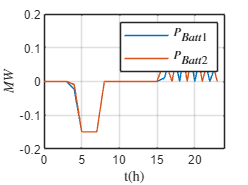


idx=0;
P_dis=[];P_ch=[];Pbatt_opt=[];
for ii=1:BatteryNum
    P_dis(:,:,ii) = x(idx+1:idx+Kday);idx=idx+Kday;
    P_ch(:,:,ii) = x(idx+1:idx+Kday);idx=idx+Kday;
    Pbatt_opt(:,:,ii) = P_dis(:,:,ii) - P_ch(:,:,ii); 
end
P_buy = x(idx+1:idx+Kday);idx=idx+Kday;
P_sell = x(idx+1:idx+Kday);
Psys_opt = P_buy-P_sell;

figure
legend_entries = cell(BatteryNum, 1);
hold on
for ii=1:BatteryNum
    plot(0:1:23, Pbatt_opt(:,:,ii)');
    legend_entries{ii} = sprintf('$P_{Batt%d}$', ii);
end
hold off
xlabel('t(h)','Interpreter','latex');
ylabel('$MW$','Interpreter','latex');
xlim([0,24])
legend(legend_entries, 'Interpreter', 'latex')
grid on
box on


%-------------------------------%
fprintf('MPC EMS daily scheduling time cost: %fs\n', dayahead_linprog_timecost);

MPC EMS daily scheduling time cost: 0.166626s


mean(dayahead_linprog_timecost)

ans = 0.1666


for ii=1:BatteryNum
    Pbatt_opt_Dec(:,:,ii)=repelem(Pbatt_opt(:,:,ii),deciFreqTime,1);
end

### Simulation of the EMS scheduling results

tic
for RealStep = 1:DecisionLevelSteps*length(t)
    decisionStep=ceil(RealStep*dt*deciFreqTime);
    
    if RealStep==1
        S_load_vec=Pload_true_box(:,RealStep)+1j*Qload_true_box(:,RealStep);
        [Vs, Vinv, Xbasic(:,RealStep)]=InitializationProgram(Pload_true_box,Qload_true_box,S_DieselG_vec,PV1_curve,V_DC,Xm_g,Zmv_g,Y_Bus,Line,controlParams,K_Vdp,K_fdp,BusOfSlack,BusOfBattery,BusOfPV,BusNum,BatteryNum,SolarNum,dt);
        S_slack_ini=-sum(S_load_vec);

        Niter=3;% suggest value >=
    else
        S_load_vec=Pload_true_box(:,RealStep)+1j*Qload_true_box(:,RealStep);
        S_slack_ini=S_busInjVec(1);

        Niter=1;% suggest value >=
    end
    
    idx_ref=0;
    for ii=1:BatteryNum
        Ref(idx_ref+1,RealStep)=1;idx_ref=idx_ref+1;%Vset GFM
        Ref(idx_ref+1,RealStep)=0;idx_ref=idx_ref+1;%dw_set GFM
        Ref(idx_ref+1,RealStep)=Pbatt_opt_Dec(decisionStep,1,ii);idx_ref=idx_ref+1;%Pg1_bat set
        Ref(idx_ref+1,RealStep)=0;idx_ref=idx_ref+1;%Qg1_bat set
    end
    for ii=1:SolarNum
        Ref(idx_ref+1,RealStep)=min(PVInv_P_rate(BusOfPV(ii),1),PV1_curve(BusOfPV(ii),RealStep));idx_ref=idx_ref+1;%Pg2_bat set
        Ref(idx_ref+1,RealStep)=0;idx_ref=idx_ref+1;%Qg2_bat set
    end

    if BatteryNum==0 && SolarNum==0
        RefInf=[];
    else
        RefInf=Ref(:,RealStep);
    end
    
    [Xbasic(:,RealStep+1),Vs,Vinv,S_busInjVec,S_inv_Batt,S_inv_PV,fvalpf, exitflagpf]=MicrogridSys_ODEAE_expIterSolver(Xbasic(:,RealStep),Vs,Vinv,RefInf,S_slack_ini,S_load_vec,S_DieselG_vec,V_DC,Xm_g,Zmv_g,Y_Bus,controlParams,K_Vdp,K_fdp,BusOfBattery,BusOfPV,dt,Niter);
    
    
    % record results and calculate costs
    VsBoxBasic(:,RealStep)=Vs;
    Pload_BoxBasic(:,RealStep)=real(S_load_vec([residential_node business_node],:));
    Qload_BoxBasic(:,RealStep)=imag(S_load_vec([residential_node business_node],:));

    Pload_resid=real(sum(S_load_vec(residential_node,1)));
    Pload_busi=real(sum(S_load_vec(business_node,1)));
    w_c_resid=Pload_resid/(Pload_resid+Pload_busi);
    w_c_busi=Pload_busi/(Pload_resid+Pload_busi);
    C_buy(1,RealStep)=C_buy_residential(1,RealStep)*w_c_resid+C_buy_business(1,RealStep)*w_c_busi;

    idx_ref=0;
    Pbatt(:,RealStep)=real(S_inv_Batt(BusOfBattery,1));
    if BatteryNum>0
        for ii=1:BatteryNum
            Pbatt_dis(ii,1)=max(Pbatt(ii,RealStep),0);% active power injected from the storage system
            Pbatt_ch(ii,1)=max(-Pbatt(ii,RealStep),0);% active power consumed by the storage system
            SOC(ii,RealStep+1)=SOC(ii,RealStep)+inta_batt_ch*Pbatt_ch(ii,1)*dt/EbattMax-Pbatt_dis(ii,1)*dt/(EbattMax*inta_batt_dis);
        end
    else
        SOC(ii,RealStep+1)=SOC(ii,RealStep);
    end

    V_from = Vs(Line(:,1));
    V_to   = Vs(Line(:,2));
    I_line(:,RealStep) = (V_from - V_to) ./ Impedance;
    Ploss(1,RealStep) = sum(abs(I_line(:,RealStep)).^2 .* real(Impedance));

    Psys=real(S_busInjVec(1,1));
    Pbuy=max(Psys,0);% total active power injected from the large system
    Pbuy_forPowBalan=max(Pbuy-Ploss(1,RealStep),0);% additional power for load power balance

    Psell=max(-Psys,0);%active power consumed by the large system

    CostRecord(1,RealStep)=(C_buy(1,RealStep)*Pbuy_forPowBalan*dt-C_sell(1,RealStep)*Psell*dt+C_buy(1,RealStep)*Ploss(1,RealStep)*dt+C_buy(1,RealStep)*(sum(Pbatt_ch*(1-inta_batt_ch))+sum(Pbatt_dis*(1-inta_batt_dis)))*dt+C_deg*sum(Pbatt_ch+Pbatt_dis)*dt+C_dieselG*real(sum(S_DieselG_vec))*dt)*1000;% MW->kW

    P_battVec_chr=min(Pbatt(:,RealStep),0);
    TotalLoad(1,RealStep)=real(sum(S_load_vec));
    TotalConsume(1,RealStep)=real(sum(S_load_vec))+sum(P_battVec_chr);
    P_battVec_gen=max(Pbatt(:,RealStep),0);
    TotalGen(1,RealStep)=sum(P_battVec_gen)+real(sum(S_inv_PV))+Psys+real(sum(S_DieselG_vec));
    TotalSys(1,RealStep)=Psys;
    TotalBatt(1,RealStep)=sum(Pbatt(:,RealStep));
    TotalPV(1,RealStep)=real(sum(S_inv_PV(BusOfPV,1)));
end
timeCostsimulationDayAhead=toc;
fprintf('MPC EMS daily simulation time cost: %fs\n', timeCostsimulationDayAhead);

MPC EMS daily simulation time cost: 45.112690s


Results display

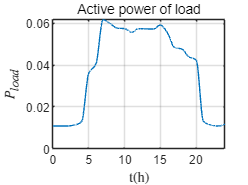

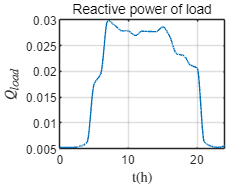

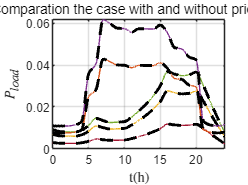

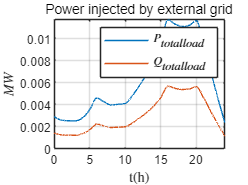

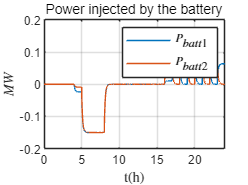

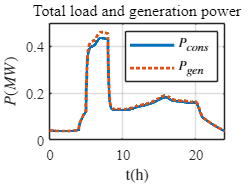

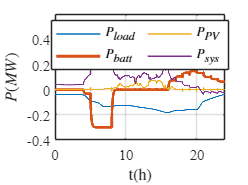

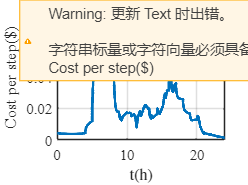

State variable for all inverters:


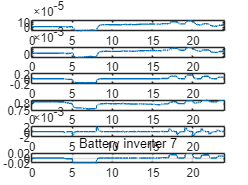

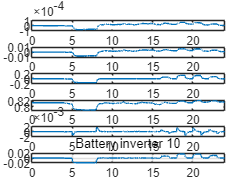

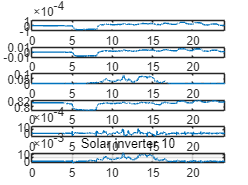

Branch current out-of-limit report:


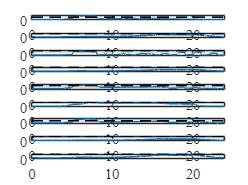

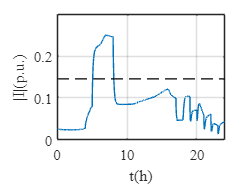

Bus voltage out-of-limit report:


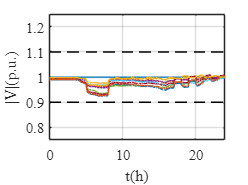

Pload_true_boxPlt=Pload_true_box([residential_node business_node],:);
[totalCost]=EMS_results_display(Pload_BoxBasic,Qload_BoxBasic,Pload_true_boxPlt,Pbatt,TotalLoad,TotalConsume,TotalGen,TotalBatt,TotalPV,TotalSys,CostRecord,VsBoxBasic,SOC,Xbasic,I_line,LineLimits,Vmin,Vmax,ResiUserNum+BusiUserNum,BusOfBattery,BusOfPV,t_sim,ExportFigForPaper,brhID);

disp(['Total cost for day-ahead LP: $',num2str(sum(CostRecord))])

Total cost for day-ahead LP: $388.1437


disp(['Average value of one step decision time cost for day-ahead LP: ',num2str(dayahead_linprog_timecost/Kday),'s'])

Average value of one step decision time cost for day-ahead LP: 0.0069427s


function [Feature, dFeature] = build_dataset(Pmat0, col_indices, lag,dt,usedx)
    Feature = [];
    dFeature = [];

    Pmat=[Pmat0(end-lag+2:end,:); Pmat0; Pmat0(1,:)];
    dP3mat=Pmat(2:end,:)-Pmat(1:end-1,:);

    for col = col_indices
        dcurve = dP3mat(:, col);
        curve = Pmat(:, col);
        n = length(curve);

        for Nt = lag:n-1
            F=curve(Nt-lag+1:Nt)';
            Feature = [Feature; F mod((Nt-lag),24)*dt/24];  % Append as a row vector

            dF=dcurve(Nt)';
            if usedx==1
            dFeature = [dFeature; dF];
            else
            dFeature = [dFeature; curve(Nt)];
            end
        end
    end
end

function [Feature, dFeature] = build_datasetPV(Pmat0, col_indices, lag,dt,usedx)
    Feature = [];
    dFeature = [];

    Pmat=[Pmat0(end-lag+2:end,:); Pmat0; Pmat0(1,:)];
    dP3mat=Pmat(2:end,:)-Pmat(1:end-1,:);

    % GHImat=[GHImat0(end-lag+2:end,:); GHImat0; GHImat0(1,:)];

    for col = col_indices
        dcurve = dP3mat(:, col);
        curve = Pmat(:, col);
        n = length(curve);

        % ghicurve= GHImat(:, col);

        for Nt = lag:n-1
            F=curve(Nt-lag+1:Nt)';
            Feature = [Feature; F  mod((Nt-lag),24)*dt/24];  % Append as a row vector

            dF=dcurve(Nt)';
            if usedx==1
            dFeature = [dFeature; dF];
            else
            dFeature = [dFeature; curve(Nt)];
            end
        end
    end
end

function [ygrid] = UniversalCurve(tAnchors, yAnchors,tgrid, method)
% UNIVERSALCURVE 
%   Build a "universal" curve that passes through user-specified anchors
%   using chosen interpolation method ('spline' or 'pchip').
% 
% Inputs:
%   tAnchors  - 1xN vector of time anchor points (e.g. hours in [0,24]), sorted ascending
%   yAnchors  - 1xN vector of function values at those times
%   method    - 'spline' or 'pchip' or 'linear' etc. (interpolation method)
%
% Outputs:
%   tgrid  - a dense grid (e.g. 15-min step from tAnchors(1) to tAnchors(end))
%   ygrid  - the interpolated function values matching tgrid
%
% Example:
%   tA = [0   6    8   14  18  24];
%   yA = [0.2 0.3  1.0 0.9 0.4 0.2];
%   [tout, yout] = UniversalCurve(tA, yA, 'pchip');
%   plot(tout,yout,'b-', tA, yA, 'ro');
%   -> gets a smooth curve passing all anchor points

    if nargin<3, method='spline'; end

    % Check input
    if length(tAnchors)~=length(yAnchors)
        error('Anchors dimension mismatch');
    end
    if any(diff(tAnchors)<=0)
        error('tAnchors must be strictly ascending');
    end

    % Interpolate
    switch lower(method)
        case {'spline','pchip','linear','makima'}
            ygrid = interp1(tAnchors, yAnchors, tgrid, method);
        otherwise
            error('Unknown method: %s. Use e.g. "spline","pchip","linear","makima".', method);
    end
    % ygrid=ygrid/max(ygrid);
end





function F = complex_power_flow_eq_ini(decision_real_imag,Vinf, Ybus,S_GFL,S_load)

    n = length(decision_real_imag) / 2;
    Real=decision_real_imag(1:n);
    Imag=decision_real_imag(n+1:end);

    Vs_real = [real(Vinf);Real(2:end)];  % Vs real part
    PinfBus_real = Real(1,1);

    Vs_imag = [imag(Vinf);Imag(2:end)];  % Vs imag part
    QinfBus_imag = Imag(1,1);

    Vbus = Vs_real + 1i * Vs_imag;  

    S_sys=zeros(size(S_load));
    S_sys(1,1)=PinfBus_real+1j*QinfBus_imag;

    left_side = Vbus .* conj(Ybus * Vbus);
    right_side =  S_sys + S_GFL + S_load;

    F_real = real(left_side - right_side);  
    F_imag = imag(left_side - right_side);  

    F = [F_real; F_imag];
end

function K=compositeKernel(x1, x2, sigma)
    K = GaussianKernel(x1,x2,sigma);
end

function y=GaussianKernel(x1,x2,sigma)
    x1=x1(:);
    x2=x2(:);
    diff = x1 - x2;
    y = exp( - (diff' * diff) / (2 * sigma^2) );
end



function Xnext=LoadPredModel(X,X_train,best_sigma,alpha_best,StdTime)
% X is the input vector formed by i-lag+1 to i-th point

    % Use the previous 'lag' predicted points as input
    x = [X StdTime];  % Row vector of length 'lag'

    % Compute kernel values between x and each training sample (vectorized)
    for kk=1:size(X_train,1)
        kx(1,kk)=compositeKernel(X_train(kk,:),x,best_sigma); 
    end
    
    % Predict the current point using the kernel ridge regression model
    dx = kx * alpha_best;
    Xnext = dx+X(1, end);
end

function Xnext=SolarPredModel(X,X_train,best_sigma,alpha_best,Pmat_dictionary,NextPoint,predStep,useUpStream,lookAheadStep,StdTime)
% X is the input vector formed by i-lag+1 to i-th point

    % Use the previous 'lag' predicted points as input
    x = [X StdTime];  % Row vector of length 'lag'

    % Compute kernel values between x and each training sample (vectorized)
    for kk=1:size(X_train,1)
        kx(1,kk)=compositeKernel(X_train(kk,:),x,best_sigma); 
    end
    
    % Predict the current point using the kernel ridge regression model
    dx = kx * alpha_best;
    xnextEsti = dx+X(1, end);

    % make prediction based on the typical curve table
    [~,inds] = knnCPU(Pmat_dictionary(1,:)',X(end),1);
    xnextEsti_exp = Pmat_dictionary(2,max(inds));
    if useUpStream==1 && predStep<=lookAheadStep
        Xnext = NextPoint;
    else
        Xnext = xnextEsti*0.5+xnextEsti_exp*0.5;
    end
end

function [totalCost]=EMS_results_display(Pload_BoxBasic,Qload_BoxBasic,Pload_true_boxPlt,Pbatt,TotalLoad,TotalConsume,TotalGen,TotalBatt,TotalPV,TotalSys,CostRecord,VsBoxBasic,SOC,Xbasic,I_line,LineLimits,Vmin,Vmax,BusOfLoad,BusOfBattery,BusOfPV,t_sim,ExportFigForPaper,brhID)
    fontsize=10;

    tTol=t_sim(1,1:end);
    ctTol=length(tTol);

    BatteryNum=length(BusOfBattery);
    SolarNum=length(BusOfPV);
    
    figure
    % legend_entries = cell(BusNum, 1); % Pre-allocate legend entries
    for ii=1:BusOfLoad
        plot(tTol,-Pload_BoxBasic(ii,1:ctTol));
        % legend_entries{ii} = sprintf('bus %d', ii); % Add LaTeX legend entry
    end
    title('Active power of load');
    xlabel('t(h)','Interpreter','latex');ylabel('$P_{load}$','Interpreter','latex');
    xlim([0,24])
    grid on
    box on

    figure
    % legend_entries = cell(BusNum, 1); % Pre-allocate legend entries
    for ii=1:BusOfLoad
        plot(tTol,-Qload_BoxBasic(ii,1:ctTol));
        % legend_entries{ii} = sprintf('bus %d', ii); % Add LaTeX legend entry
    end
    title('Reactive power of load');
    xlabel('t(h)','Interpreter','latex');ylabel('$Q_{load}$','Interpreter','latex');
    xlim([0,24])
    grid on
    box on

    figure
    hold on
    % legend_entries = cell(BusNum, 1); % Pre-allocate legend entries
    for ii=1:BusOfLoad
        plot(tTol,-Pload_BoxBasic(ii,1:ctTol));
        plot(t_sim,-Pload_true_boxPlt(ii,:), 'k--','LineWidth',2);
        % legend_entries{ii} = sprintf('bus %d', ii); % Add LaTeX legend entry
    end
    hold off
    title('Comparation the case with and without price adj.');
    xlabel('t(h)','Interpreter','latex');ylabel('$P_{load}$','Interpreter','latex');
    xlim([0,24])
    grid on
    box on


    figure
    hold on
    plot(tTol,-Pload_BoxBasic(1,1:ctTol));
    plot(tTol,-Qload_BoxBasic(1,1:ctTol));
    hold off
    title('Power injected by external grid');
    xlabel('t(h)','Interpreter','latex');ylabel('$MW$','Interpreter','latex');
    xlim([0,24])
    legend({'$P_{total load}$','$Q_{total load}$'},'Interpreter','latex')
    grid on
    box on
    
    figure
    hold on
    legend_entries = cell(BatteryNum, 1); % Pre-allocate legend entries
    for ii = 1:BatteryNum
        plot(tTol, Pbatt(ii, 1:ctTol));
        legend_entries{ii} = sprintf('$P_{batt%d}$', ii); % Add LaTeX legend entry
    end
    hold off
    title('Power injected by the battery');
    xlabel('t(h)', 'Interpreter', 'latex');
    ylabel('$MW$', 'Interpreter', 'latex');
    xlim([0,24])
    grid on
    box on
    legend(legend_entries, 'Interpreter', 'latex')
    
    figure
    hold on
    plot(tTol,real(-TotalConsume(1,1:ctTol)),'LineWidth',2);
    plot(tTol,real(TotalGen(1,1:ctTol)),':','LineWidth',2);
    hold off
    title('Total load and generation power');
    xlabel('t(h)','Interpreter','latex');ylabel('$P(MW)$','Interpreter','latex');
    xlim([0,24])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    legend({'$P_{cons}$','$P_{gen}$'},'Interpreter','latex')
    grid on
    box on

    figure
    hold on
    plot(tTol,real(TotalLoad(1,1:ctTol)),'LineWidth',1);
    plot(tTol,TotalBatt(1,1:ctTol),'LineWidth',2);
    plot(tTol,TotalPV(1,1:ctTol),'LineWidth',1);
    plot(tTol,TotalSys(1,1:ctTol),'LineWidth',1);
    hold off
    legend({'$P_{load}$','$P_{batt}$','$P_{PV}$','$P_{sys}$'},'Interpreter','latex','Location','best','NumColumns',2)
    xlabel('t(h)','Interpreter','latex');ylabel('$P(MW)$','Interpreter','latex');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    xlim([0,24])
    % ylim([1.5*min(TotalLoad),1.5*max(TotalSys)])
    % title('All power');
    grid on
    box on
    if ExportFigForPaper==1
        w=7.8;%cm
        h=7;%cm
        filename='AllPowerCurve';
        format='pdf';
        figProcess(w, h, filename, format);
    end

    figure
    plot(tTol,CostRecord(1,1:ctTol),'LineWidth',2);
    ylabel('Cost per step($)','Interpreter','latex');
    xlabel('t(h)','Interpreter','latex');
    xlim([0,24])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    % disp(['Total cost: ',num2str(sum(CostRecord))])
    grid on
    box on
    totalCost=sum(CostRecord);
    
    figure
    legend_entries = cell(BatteryNum, 1); % Pre-allocate legend entries
    hold on
    for ii = 1:BatteryNum
        plot(tTol,SOC(ii,1:ctTol),'LineWidth',2);
        legend_entries{ii} = sprintf('$SOC_{%d}$', ii);
    end
    plot(tTol,0.2*ones(1,ctTol),'k--','LineWidth',1);
    plot(tTol,0.9*ones(1,ctTol),'k--','LineWidth',1);
    plot(tTol,SOC(1,1)*ones(1,ctTol),'k--','LineWidth',1);
    hold off
    ylabel('SOC','Interpreter','latex');xlabel('t(h)','Interpreter','latex')
    xlim([0,24])
    ylim([0,1])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    grid on
    box on
    % legend(legend_entries, 'Interpreter', 'latex', 'Location', 'best')
    if ExportFigForPaper==1
        w=8.8*1.1;%cm
        h=3;%cm
        filename='SoC_of_Battery';
        format='pdf';
        figProcess(w, h, filename, format);
    end

    fprintf('State variable for all inverters:\n')
    idx=0;
    for jj=1:BatteryNum
        figure
        hold on
        for ii=idx+1:idx+6
            subplot(6,1,ii-idx)
            plot(tTol,Xbasic(ii,1:ctTol));
        end
        hold off
        grid on
        box on
        title(sprintf('Battery inverter %d',BusOfBattery(jj)))
    
        idx=idx+6;
    end
    for jj=1:SolarNum
        figure
        hold on
        for ii=idx+1:idx+6
            subplot(6,1,ii-idx)
            plot(tTol,Xbasic(ii,1:ctTol));
        end
        hold off
        grid on
        box on
        title(sprintf('Solar inverter %d',BusOfPV(jj)))
    
        idx=idx+6;
    end

 

    fprintf('Branch current out-of-limit report:\n')
    Iline_mag=abs(I_line);
    idx=0;
    subFigSize=size(I_line,1);
    figure
    for ii=idx+1:idx+subFigSize
        subplot(subFigSize,1,ii-idx)
        hold on
        plot(tTol,Iline_mag(ii,:))
        plot(tTol,LineLimits(ii)*ones(size(tTol)),'Color','k','LineStyle','--')
        xlim([0,24])
        % ylim([0,1.1*LineLimits(ii)])
        % title(sprintf('Branch %d', ii))
        set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
        grid on
        box on
        hold off
    end
    xlabel('t(h)');ylabel('|I|(p.u.)')

    figure%most series branch for displaying
    % brhID=1;
    hold on
    plot(tTol,Iline_mag(brhID,:))
    plot(tTol,LineLimits(brhID)*ones(size(tTol)),'Color','k','LineStyle','--')
    hold off
    xlim([0,24])
    ylim([0,max(1.5*LineLimits(brhID),1.2*max(Iline_mag(brhID,:)))])
    xlabel('t(h)');ylabel('|I|(p.u.)')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    grid on
    box on
    if ExportFigForPaper==1
        w=8.8*1.1;%cm
        h=3;%cm
        filename='BranchCurrent';
        format='pdf';
        figProcess(w, h, filename, format);
    end
    
    fprintf('Bus voltage out-of-limit report:\n')
    Vs_mag=abs(VsBoxBasic);
    figure
    hold on 
    for ii=1:size(Vs_mag,1)
        plot(tTol,Vs_mag(ii,:))
    end
    plot(tTol,Vmin*ones(size(tTol)),'Color','k','LineStyle','--')
    plot(tTol,Vmax*ones(size(tTol)),'Color','k','LineStyle','--')
    hold off
    xlabel('t(h)');ylabel('|V|(p.u.)')
    xlim([0,24])
    ylim([0.75,1.25])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fontsize);
    grid on
    box on
    if ExportFigForPaper==1
        w=8.8*1.1;%cm
        h=3;%cm
        filename='BusVoltage';
        format='pdf';
        figProcess(w, h, filename, format);
    end
end

function figProcess(w, h, filename, format)
    if nargin < 3 || isempty(filename), filename = 'figure'; end
    if nargin < 4 || isempty(format),   format   = 'pdf';    end

    fig = gcf;
    set(fig, 'Units','centimeters');
    pos = get(fig,'Position');                       % [left bottom width height]
    set(fig, 'Position', [pos(1) pos(2) w h]);       % size setting (cm)

    ax = gca;
    set(ax, 'Units','centimeters');

    
    set(fig, 'PaperUnits','centimeters', 'PaperPositionMode','auto', 'Color', 'none');

    % option
    % text(ax, 0.02, 0.95, sprintf('%.1f cm × %.1f cm', w, h), ...
    %     'Units','normalized','HorizontalAlignment','left', ...
    %     'VerticalAlignment','top','FontName','Times New Roman');

    if strcmpi(format,'pdf')
        set(fig, 'PaperSize', [w h], 'Renderer','painters');
        exportgraphics(fig, sprintf('%s.pdf', filename), 'ContentType','vector');
    elseif strcmpi(format,'png')
        exportgraphics(fig, sprintf('%s.png', filename), 'Resolution', 600);
    else
        error('format must be ''pdf'' or ''png''.');
    end
end

function [Vs, Vinv, X]=InitializationProgram(Pload_true_box,Qload_true_box,S_DieselG_vec,PV1_curve,V_DC,Xm_g,Zmv_g,Y_Bus,Line,controlParams,K_Vdp,K_fdp,BusOfSlack,BusOfBattery,BusOfPV,BusNum,BatteryNum,SolarNum,dt)
    for RealStep = 1:round(0.2/dt)       
        if RealStep==1
            % power grid
            Vs=ones(BusNum,1);
            S_load_vec=Pload_true_box(:,RealStep)+1j*Qload_true_box(:,RealStep);
            S_slack_ini=-sum(S_load_vec);
    
            % inverter
            if BatteryNum>0
                Vinv=ones(BatteryNum+SolarNum,1);
                Xbasic(:,RealStep)=zeros((BatteryNum+SolarNum)*6,1);
            else
                Vinv=0;
                Xbasic(:,RealStep)=zeros((1)*6,1);
            end
    
            Niter=10;
        else
            % update load power
            S_load_vec=Pload_true_box(:,RealStep)+1j*Qload_true_box(:,RealStep);
    
            Niter=5;
        end
        
        idx=0;
        for ii=1:BatteryNum
            Ref(idx+1,RealStep)=1;idx=idx+1;%Vset GFM
            Ref(idx+1,RealStep)=0;idx=idx+1;%dw_set GFM
            Ref(idx+1,RealStep)=0;idx=idx+1;%Pg1_bat set
            Ref(idx+1,RealStep)=0;idx=idx+1;%Qg1_bat set
        end

        for ii=1:SolarNum
            Ref(idx+1,RealStep)=PV1_curve(1,RealStep);idx=idx+1;%Pg2_bat set
            Ref(idx+1,RealStep)=0;idx=idx+1;%Qg2_bat set
        end

        if BatteryNum==0 && SolarNum==0
            RefInf=[];
        else
            RefInf=Ref(:,RealStep);
        end
        
        [Xbasic(:,RealStep+1),Vs,Vinv,S_busInjVec,S_inv_Batt,S_inv_PV,~, ~]=MicrogridSys_ODEAE_expIterSolver(Xbasic(:,RealStep),Vs,Vinv,RefInf,S_slack_ini,S_load_vec,S_DieselG_vec,V_DC,Xm_g,Zmv_g,Y_Bus,controlParams,K_Vdp,K_fdp,BusOfBattery,BusOfPV,dt,Niter);
        
    end
    X=Xbasic(:,end);
end